% routine to run y analysis of single fish data

% define colormaps for lines 

Cmap = LineMap;
Fs = 22; % frames per seconds (from movie file)
% folder where .csv and .mp4 files are places
% change to your folder
% Folder = 'D:\Sleeping fish\data\'; 
SAVE = 1; % saves plotted data such as shelters etc'


if ispc % if this is a pc computer
    % put in the folder where all csv file are at
    Folder = 'E:\sleepexp\final data DD-LD for analysation by Roy'; 
% put here the folder where you want files to be saved to (right now only
% .fig files are saved)
else % if this is a mac computer:
    Folder = '/Users/royharpaz/Dropbox/Collaborations/CoralFish/Single_fish_data_second_exp/'; 
    save_folder = '/Users/royharpaz/Dropbox/Collaborations/CoralFish/For Shachaf/Results_single_fish/';

    
end
% important decide if to save files and make a movie as default (I usually
% leave it as 0, and change it only if I need to).
SAVE = 0;

cd(Folder); % change to folder location

Nfish = 11; % numebr of fish

fish_i = 1:Nfish;

experiment_day = 1:2; % experimental days
experiment_cond = {'LD','DD'};
experiment_time = {'day','night'};
experiment_time_alternate = {'d','n'}; % this is since some files as 'd' instead of 'day'

Nf = length(fish_i); % number of fish


coor = cell(length(fish_i),length(experiment_day),length(experiment_cond),...
    length(experiment_time)); % [fish,day,condition (LD,DD), time (day,night)
filenames = coor;
fish_id = zeros(size(coor));

% load the coordinates
for f = 1:length(fish_i)
    for c = 1:length(experiment_cond)
        for d = 1:length(experiment_day)
            for t = 1:length(experiment_time)
                name = sprintf('FISH%d%s%s%d_filtered.csv',f,experiment_cond{c},...
                    experiment_time{t},experiment_day(d));
                alternate_name = sprintf('FISH%d%s%s%d_filtered.csv',f,experiment_cond{c},...
                    experiment_time_alternate{t},experiment_day(d));
                if exist(name,'file')
                    coor{f,d,c,t} = csvread(name,3,1);
                    filenames{f,d,c,t} = name;
                    disp(name)
                elseif exist(alternate_name,'file')
                    coor{f,d,c,t} = csvread(alternate_name,3,1);
                    filenames{f,d,c,t} = alternate_name;
                    disp(alternate_name)
                else
                    disp([name, ' missing']);
                end
                fish_id(f,c,d,t) = f;
            end
        end
    end
    
end

FISH1LDday1_filtered.csv
FISH1LDnight1_filtered.csv
FISH1LDday2_filtered.csv
FISH1LDnight2_filtered.csv
FISH1DDday1_filtered.csv
FISH1DDnight1_filtered.csv
FISH1DDday2_filtered.csv
FISH1DDnight2_filtered.csv
FISH2LDday1_filtered.csv
FISH2LDnight1_filtered.csv
FISH2LDday2_filtered.csv
FISH2LDnight2_filtered.csv
FISH2DDday1_filtered.csv
FISH2DDnight1_filtered.csv
FISH2DDday2_filtered.csv
FISH2DDnight2_filtered.csv
FISH3LDday1_filtered.csv
FISH3LDnight1_filtered.csv
FISH3LDday2_filtered.csv
FISH3LDnight2_filtered.csv
FISH3DDday1_filtered.csv
FISH3DDnight1_filtered.csv
FISH3DDday2_filtered.csv
FISH3DDnight2_filtered.csv
FISH4LDday1_filtered.csv
FISH4LDnight1_filtered.csv
FISH4LDday2_filtered.csv
FISH4LDnight2_filtered.csv
FISH4DDday1_filtered.csv
FISH4DDnight1_filtered.csv
FISH4DDday2_filtered.csv


FISH4DDnight2_filtered.csv missing


FISH5LDday1_filtered.csv
FISH5LDnight1_filtered.csv
FISH5LDday2_filtered.csv
FISH5LDnight2_filtered.csv
FISH5DDday1_filtered.csv
FISH5DDnight1_filtered.csv
FISH5DDday2_filtered.csv
FISH5DDnight2_filtered.csv


FISH6LDd1_filtered.csv
FISH6LDn1_filtered.csv
FISH6LDd2_filtered.csv


FISH6LDnight2_filtered.csv missing


FISH6DDd1_filtered.csv
FISH6DDn1_filtered.csv
FISH6DDd2_filtered.csv
FISH6DDn2_filtered.csv


FISH7LDday1_filtered.csv missing
FISH7LDnight1_filtered.csv missing
FISH7LDday2_filtered.csv missing
FISH7LDnight2_filtered.csv missing
FISH7DDday1_filtered.csv missing
FISH7DDnight1_filtered.csv missing
FISH7DDday2_filtered.csv missing
FISH7DDnight2_filtered.csv missing


FISH8LDd1_filtered.csv
FISH8LDn1_filtered.csv
FISH8LDd2_filtered.csv
FISH8LDn2_filtered.csv
FISH8DDd1_filtered.csv
FISH8DDn1_filtered.csv
FISH8DDd2_filtered.csv
FISH8DDn2_filtered.csv


FISH9LDday1_filtered.csv missing
FISH9LDnight1_filtered.csv missing
FISH9LDday2_filtered.csv missing
FISH9LDnight2_filtered.csv missing
FISH9DDday1_filtered.csv missing
FISH9DDnight1_filtered.csv missing
FISH9DDday2_filtered.csv missing
FISH9DDnight2_filtered.csv missing


FISH10LDd1_filtered.csv
FISH10LDn1_filtered.csv
FISH10LDd2_filtered.csv
FISH10LDn2_filtered.csv
FISH10DDd1_filtered.csv
FISH10DDn1_filtered.csv
FISH10DDd2_filtered.csv
FISH10DDn2_filtered.csv
FISH11LDd1_filtered.csv
FISH11LDn1_filtered.csv
FISH11LDd2_filtered.csv
FISH11LDn2_filtered.csv
FISH11DDd1_filtered.csv
FISH11DDn1_filtered.csv
FISH11DDd2_filtered.csv
FISH11DDn2_filtered.csv


            
% get length of experiments
Lframes = cellfun(@length,coor);


% load fish frames and define shelter positions
frame_folder = [Folder,'frames/'];
all_frames = cell(1,Nf);
if ~exist([frame_folder,'shelters.mat'],'file')
    
    shelter = cell(1,Nf);
    for i = 1:Nf
        frame_name = [frame_folder,'FISH',num2str(i),'.png'];
        if exist(frame_name,'file')
            frame = imread(frame_name);
            all_frames{i} = frame;
        else
            continue
        end
        
        h_im = imshow(rgb2gray(frame)); hold on;
        title(['draw polygon around shelter, fish:',num2str(i)]);
        h = impoly;
        position = wait(h);
        ex_borders = getPosition(h);
        shelter{i} = ex_borders;
        clf
        % add exclusion to Msk:
        
    end
else
    load([frame_folder,'shelters.mat']);
    load([frame_folder,'all_frames.mat']);

end


if SAVE
   save([frame_folder,'shelters'],'shelter'); 
   save([frame_folder,'all_frames'],'all_frames'); 
end

% load fish frames and define horizontal axis
frame_folder = [Folder,'frames/'];
num_points = 2; % nuber of points on the file
if ~exist([frame_folder,'Horz_axis.mat'],'file')
    horz_axis = zeros(Nf,num_points,2); %[num fish, num poitns, xy];
    for i = 1:Nf
        frame_name = [frame_folder,'FISH',num2str(i),'.png'];
        if exist(frame_name,'file')
            frame = imread(frame_name);
        else
            continue
        end
        
        h_im = imshow(rgb2gray(frame)); hold on;
        
        title(['draw horizotnal line on the top of the shelter, fish:',num2str(i)]);
        h = imline;
        position = wait(h);
        ex_borders = getPosition(h);
        horz_axis(i,:,:) =ex_borders;
        clf
        % add exclusion to Msk:
        
    end
    
else
    load([frame_folder,'Horz_axis.mat']);
end

if SAVE
   save([frame_folder,'Horz_axis'],'horz_axis'); 
end


% define pix/cm conversion per fish:
pix_to_cm = zeros(Nfish,1);
line_in_cm = 10; % real world size of line in cm;
for i = 1:Nfish
    curr_horz_axis = squeeze(horz_axis(i,:,:)); %[ x, y]
    curr_D = calculateNorm(diff(curr_horz_axis));
    pix_to_cm(i) = curr_D./line_in_cm;
end

% define some points for the fish
Titles = filenames;

Num_points_per_fish = 3; %

% Set points for body [1 head, 2 dorsal fin, 3 caudal fin
p1 = 1; % head point 
p2 = 2; % back point
p3 = 3; % caudal fin



% definet vectors to act as referance axis for fish motion and body posture:
horz_vec = zeros(Nf,2);
for i = 1:Nf
   temp1 =  squeeze(horz_axis(i,1,:));
   temp2 =  squeeze(horz_axis(i,2,:));
   horz_vec(i,:) = (temp2-temp1)./norm(temp2-temp1);
end

% angle of reference vec from x axis:
[~,ang_left_from_x] = angOfVectors([1 0],horz_vec,1);
% [~,ang_right_from_x] = angOfVectors([1 0],vec_right,1);

## pre precess fish data:

[xc,yc,Sc,Ang,q] = preProcessSleepingFisData(coor,fish_id,[p1,p2,p3],...
    horz_vec);

 removing points_on_fish with speed > 40 and quality < 0.9
Finished correcting experiment #1
Finished correcting experiment #2
Finished correcting experiment #3
Finished correcting experiment #4
Finished correcting experiment #5
Finished correcting experiment #6
Finished correcting experiment #8
Finished correcting experiment #10
Finished correcting experiment #11
Finished correcting experiment #12
Finished correcting experiment #13
Finished correcting experiment #14
Finished correcting experiment #15
Finished correcting experiment #16
Finished correcting experiment #17
Finished correcting experiment #19
Finished correcting experiment #21
Finished correcting experiment #22
Finished correcting experiment #23
Finished correcting experiment #24
Finished correcting experiment #25
Finished correcting experiment #26
Finished correcting experiment #27
Finished correcting experiment #28
Finished correcting experiment #30
Finished correcting experiment #32
Finished correcting experiment #33
Fin


% normalize speed to cm/s
for i = 1:length(Sc(:))
    Sc{i} = Sc{i}./pix_to_cm(fish_id(i))*Fs;
end

## plot speed over time for all fish

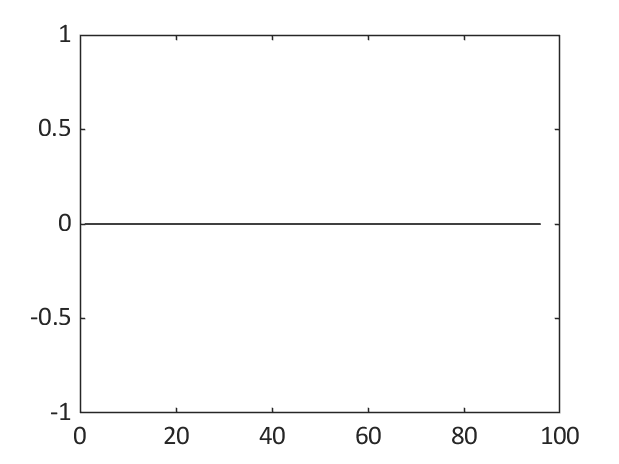

Output argument "xp" (and maybe others) not assigned during call to "boundedLine>calcpatch".

Error in boundedLine (line 298)
    [xp{iln}, yp{iln}] = calcpatch(plotdata{iln,1}, plotdata{iln,2}, isvert, plotdata{iln,6}, plotdata{iln,7});

Error in plotContProperty (line 101)
boundedLine(tt,M,stde);

time_bin = 20;
[binned_speed,continous_binned_speed] = plotContProperty(Sc,time_bin,'Fs',Fs,'PLOT',...
    1,'prop_i',1);

xlabel('Time [h]');
ylabel('Speed [cm/s]');

## plot body_angle over time for all fish

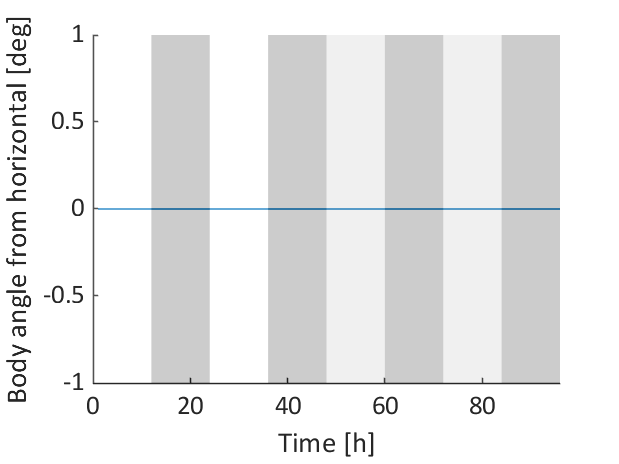

time_bin = 20;
[binned_body_angle,continous_binned_body_angle] = plotContProperty(Ang,time_bin,...
    'Fs',Fs,'PLOT',1,'prop_i',1);
xlabel('Time [h]');
ylabel('Body angle from horizontal [deg]');

## distance to center of shelter and in/out of shelter:

D_to_shelter = cell(size(xc));
in_shelter = cell(size(xc));

for i = 1:length(xc(:))
    if ~isempty(xc{i})
    % current shelter
    curr_shelter = shelter{fish_id(i)};
    center_shelter = mean(curr_shelter);
    shelter_x = center_shelter(1);
    shelter_y = center_shelter(2);
    
    % current fish position
    tempx = xc{i}(:,1);
    tempy = yc{i}(:,1);
    
    % distance to shelter center
    tempD = calculateNorm([tempx-shelter_x tempy-shelter_y]);
    D_to_shelter{i} = tempD/pix_to_cm(fish_id(i));
    
    % in shelter:
    temp_in = inpolygon(tempx,tempy,curr_shelter(:,1),curr_shelter(:,2));
    in_shelter{i} = temp_in;
    end
end

Index exceeds the number of array elements (1).

## distance from shelter over time for all fish

time_bin = 20;
[binned_dist_to_center,cont_binned_dist_to_center] = plotContProperty(D_to_shelter,...
    time_bin,'Fs',Fs,'PLOT',1,'prop_i',1);
xlabel('Time [h]');
ylabel('Distance from shelter [cm]');

## time in shelter

time_bin = 20;
[binned_time_in_shelter,cont_binned_time_in_shelter] = plotContProperty(in_shelter,...
    time_bin,'Fs',Fs,'PLOT',1,'prop_i',1);
xlabel('Time [h]');
ylabel('Time in shelter [%]');

## look at the trajectory of the fish just to see that it is ok

f_ii = 1;
day = 2;
LD_DD = 1;
d_n = 1;

frame = all_frames{f_ii};
curr_shelter = shelter{f_ii};
center_shelter = mean(curr_shelter);
x = xc{f_ii,day,LD_DD,d_n}; % [fish,day,condition (LD,DD), time (day,night)
y = yc{f_ii,day,LD_DD,d_n};
A = Ang{f_ii,day,LD_DD,d_n}(:,1);
S = Sc{f_ii,day,LD_DD,d_n}(:,1);
Slim = prctile(S,95); % y limit
Slim = max([Slim, 25]);
time_to_show = 100; % numebr of frames to plot

start_frame = 100000;
end_frame = start_frame + 1000; 

figure('Units','Normalized','Position',[0 0 1 1]);
for  t = start_frame: end_frame
    % plot the fish dots on the frame 
    subplot(3,4,[1:3,5:7,9:11])
    imagesc(frame); colormap gray; axis image;
     hold on;
%     plot(center_shelter(1),center_shelter(2),'.');
   
    % plot the body angle
    plot(x(t,:),y(t,:),'.');
    pause(0.1)
    title(t)
    hold off;
    subplot(3,4,4);
    plot(-time_to_show:+time_to_show,A(t-time_to_show:t+time_to_show)); hold on;
    xlim([-time_to_show time_to_show]);
    plot([0 0],[-120 120],'k--');
    ylim([-120 120]);
    ylabel('Body angle [deg]'); xlabel('Time [frames]');
    hold off;
    box off
    
    % plot the speed.
    subplot(3,4,8);
    plot(-time_to_show:+time_to_show,S(t-time_to_show:t+time_to_show)); hold on;
    xlim([-time_to_show time_to_show]);
    plot([0 0],[0 Slim],'k--');
    ylim([0 Slim]);
    ylabel('Speed [cm/s]'); xlabel('Time [frames]');
    hold off;
    box off
end